# 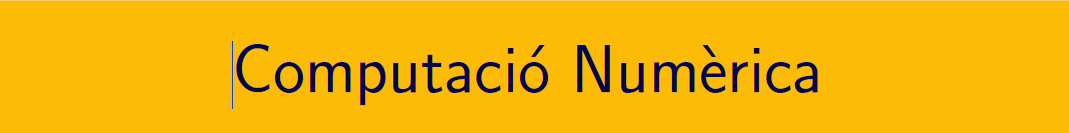

================================================================================

# Pràctica 13. Equacions diferencials ordinàries (III).

`Document preparat per M. Àngela Grau Gotés - 24 de maig de 2023`

## Mètodes multipas

## **Exercici  **$y^{\prime}(t)=y(t)+t^2\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

Solució analítica

clearvars
syms y(t)
eqn = diff(y,t) == y+t^2;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{t}-2\,t-t^{2}-2$$

La solució es pot respresentar a l'interval [0,1]

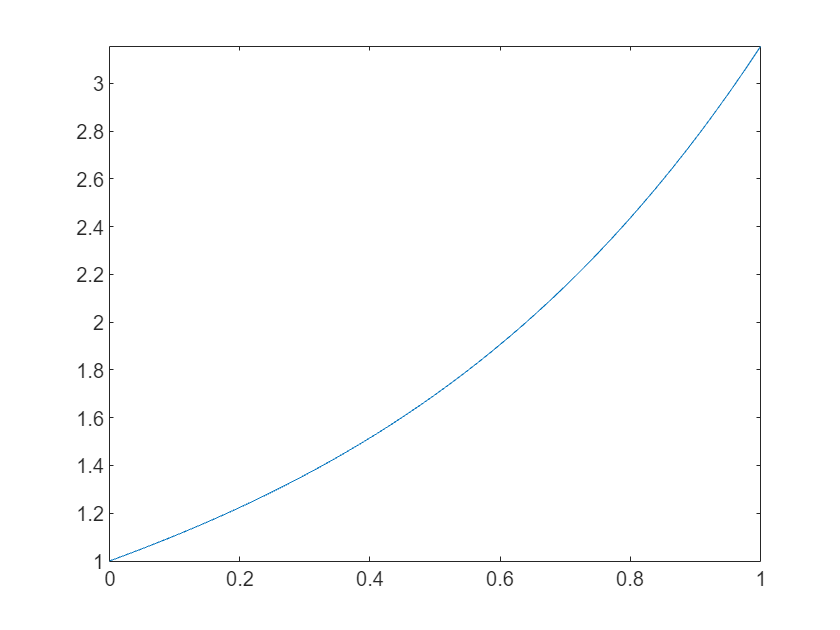

fplot(ySol,[0,1])

## Solucions aproximades numèricament O(h^4)

- `Mètode RK4`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;                % y(b) = ...
f = @(t,y)(y+t.^2);



- Mètode Adams-Basforth

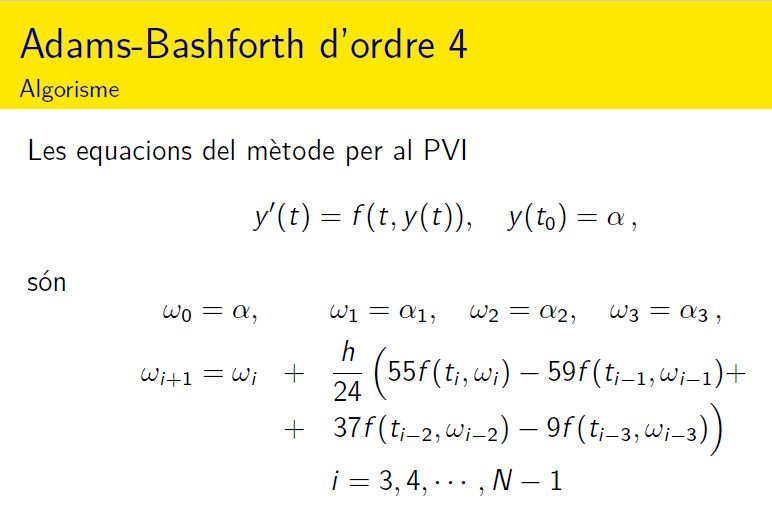

- Mètode Adams-Basforth, els primers calculats exactament

% Mètode de  Adams-Basforth
% iniciem per valor exacte
h = 0.1;
t=[a:h:b];
N=length(t);
w(1) = alpha;
w2 = RK4(f, a, b, h, alpha);
w(2) = w2(2);
w(3) = w2(3);
w(4) = w2(4);
for i=4:N-1
     a1 = 55*f(t(i),w(i));
     a2 = -59*f(t(i-1),w(i-1));
     a3 = 37*f(t(i-2),w(i-2));
     a4 = -9*f(t(i-3),w(i-3));
     s = h*(a1+a2+a3+a4);
     w(i+1)= w(i)+s/24;
end
wSol = w;

E = abs(double(ySol(t))-wSol);
disp(table(t',double(ySol(t))',wSol',E','VariableNames',{'t','Y','Y_AB','E_{local}'}))

     t            Y                  Y_AB               E_{local}      
    ___    ________________    ________________    ____________________
      0                   1                   1                       0
    0.1    1.10551275422694    1.10551270833333     4.5893609579295e-08
    0.2    1.22420827448051    1.22420815112934    1.23351169056818e-07
    0.3    1.35957642272801    1.35957618422374    2.38504270333451e-07
    0.4    1.51547409292381    1.51546109849044    1.29944333722154e-05
    0.5    1.69616381210038    1.69613381834277    2.99937576160314e-05
    0.6    1.90635640117153    1.90630715440123    4.92467702974952e-05
    0.7    2.15125812241143     2.1511857927178    7.23296936300244e-05
    0.8     2.4366227854774    2.43652286722645    9.99182509575647e-05
    0.9    2.76880933347085    2.76867685170505    0.000132481765799497


- Mètode Adams-Basforth, els primers calculats per RK4

% Mètode de  Adams-Basforth
% iniciem per RK4




function  w  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1=h*f(t(i),w(i));
        k2=h*f(t(i)+h/2,w(i)+k1/2);
        k3=h*f(t(i)+h/2,w(i)+k2/2);
        k4=h*f(t(i+1),w(i)+k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end
%---------------------------------------
function [ w ] = Euler( f,a,b,h,alpha )
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
    for i=1:N-1
        w(i+1)=w(i)+h*f(t(i),w(i));
    end
end
%---------------------------------------